clear all
close all
clc

rng(1);

load('Benchmark_EEG_small')


Preprocessing Data

partici = 2    %Choose participant

partici = 2


% [input,output] = cleanEEG(EEGdata,partici);   %Clean data, normalize and sort input and output signal

input = squeeze(data.u(partici,:,:))'  /6+0.5

input =     0.6829    0.6035    0.6430    0.3712    0.4467    0.5536    0.4999
    0.6214    0.6103    0.6208    0.4095    0.4687    0.5546    0.4646
    0.5653    0.6067    0.5884    0.4521    0.4869    0.5476    0.4437
    0.5194    0.5960    0.5521    0.4927    0.5002    0.5353    0.4360
    0.4869    0.5821    0.5189    0.5257    0.5077    0.5217    0.4378
    0.4692    0.5690    0.4950    0.5469    0.5087    0.5114    0.4440
    0.4657    0.5598    0.4848    0.5546    0.5033    0.5080    0.4493
    0.4744    0.5569    0.4895    0.5498    0.4925    0.5134    0.4496
    0.4927    0.5611    0.5075    0.5356    0.4780    0.5275    0.4424
    0.5176    0.5727    0.5341    0.5166    0.4620    0.5474    0.4278


output = squeeze(data.y(partici,:,:))' /8+0.5

output =     0.4415    0.5921    0.5096    0.5572    0.2752    0.4893    0.5731
    0.4846    0.6178    0.4981    0.5831    0.2925    0.5399    0.6078
    0.4731    0.5083    0.5403    0.5459    0.3284    0.5891    0.6376
    0.4549    0.3672    0.6292    0.5295    0.3708    0.5558    0.7176
    0.4188    0.3310    0.6865    0.5772    0.4068    0.4015    0.7594
    0.3856    0.4036    0.6644    0.6684    0.3993    0.2762    0.7105
    0.3901    0.4948    0.6483    0.7321    0.3558    0.2877    0.6409
    0.4262    0.5259    0.6933    0.6652    0.3243    0.3868    0.6247
    0.5008    0.5329    0.7004    0.5044    0.3095    0.4801    0.6799
    0.5617    0.5501    0.6349    0.4009    0.3124    0.5154    0.7152


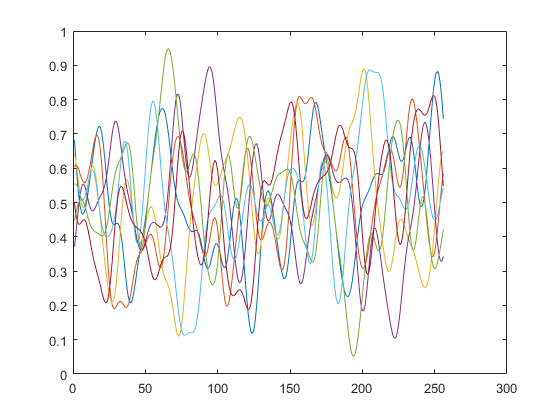


plot(input)

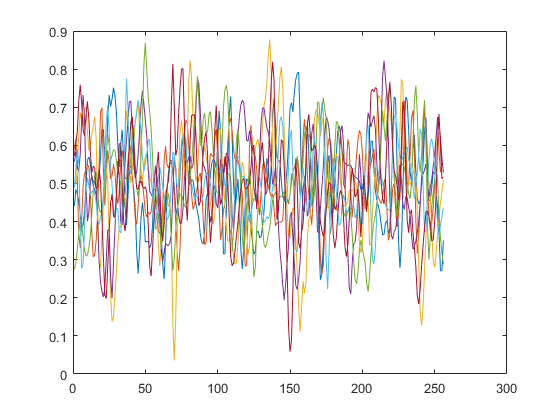

plot(output)

Choose lags

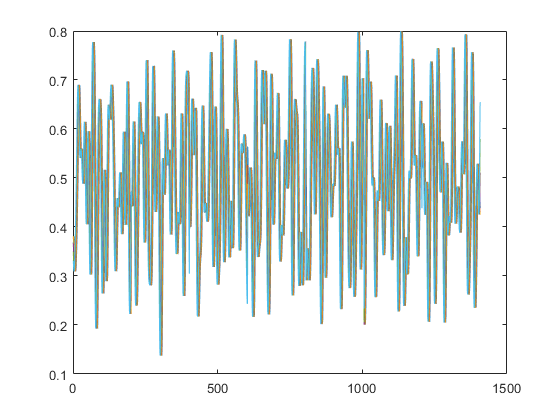

%angle
inlags=[6 5 4];
for l = 1:length(inlags)
u(:,l) = (reshape(input(end-inlags(l)-201:end-inlags(l)-1,:), [],1));
end

%angular velocity
vlags=[10 9 8 6 5 4];
for l = 1:length(vlags)
v(:,l) = (reshape(input(end-vlags(l)-201:end-vlags(l)-1,:), [],1) - reshape(input(end-vlags(l)-200:end-vlags(l),:), [],1))/0.2+0.5;
end

plot(v)


%output
outlags=[0 1 2 3 4 5];
for l = 1:length(outlags)
y(:,l) = reshape(output(end-outlags(l)-200:end-outlags(l),:), [],1);
end


Split test and training set

testind = [1:200];
trainind = setdiff([1:size(u,1)],testind);

featurez = [u(trainind,:) v(trainind,:) y(trainind,2:end)];
zeta = y(trainind,1);

tfeaturez = [u(testind,:) v(testind,:) y(testind,2:end)];
yt = y(testind,1);

% tfeaturez = featurez(1:400,:);
% yt = zeta(1:400,:);

Construct B-spline basis vectors


[N, d]=size(featurez); 

n = 2;                 %degree B-spline
m = 2;                  %Number of knot intervals
In = n+m;               %Number of B-splines

un = basisvectors(featurez,n,m);




Initialize tensor train

% Choose TT-ranks
maxrank = 8;
r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank))

r =      1     4     8     8     8     8     8     8     8     8     8     8     8     4     1



[TN,Vm,Vp] = initTT(un,r,d);


Show storage compression ratio


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %Degrees of freedom/ TT storage size.
disp(['Compression: ' num2str(dof/Pcount)])  %ratio

Compression: 1.061e-05


Optimize TT cores

lambda=10^-0

lambda = 1

difforder=2;
MAXITR = d;

% nselect = floor(logspace(log10(dof/N),0,MAXITR)*0.5*N);

% MAXITR = 2;
nselect = ones([1,MAXITR])*N

nselect =         1207        1207        1207        1207        1207        1207        1207        1207        1207        1207        1207        1207        1207        1207


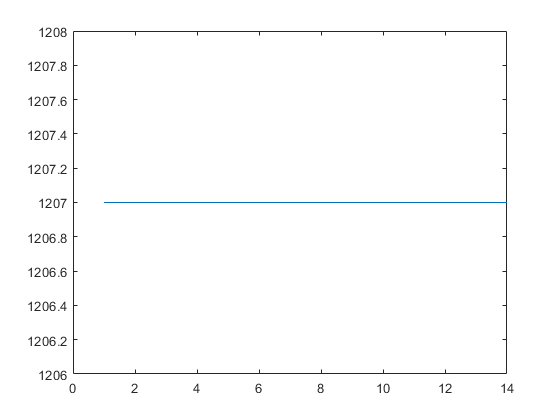

plot(nselect)


[TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,nselect,lambda,difforder);

    "iteration:"    "2"    "0.15452"

    "iteration:"    "3"    "0.30489"

    "iteration:"    "4"    "0.45006"

    "iteration:"    "5"    "0.59323"

    "iteration:"    "6"    "0.73635"

    "iteration:"    "7"    "0.89039"

    "iteration:"    "8"    "1.0369"

    "iteration:"    "9"    "1.1846"

    "iteration:"    "10"    "1.33"

    "iteration:"    "11"    "1.4735"

    "iteration:"    "12"    "1.616"

    "iteration:"    "13"    "1.7635"

    "iteration:"    "14"    "1.9184"



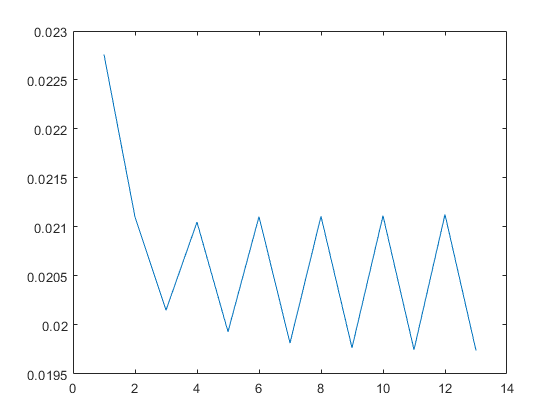


plot(res1)

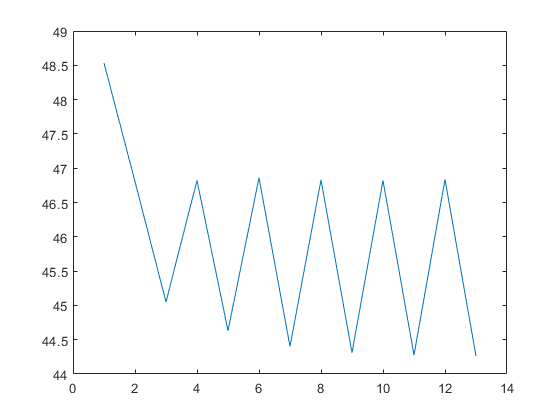

plot(res2)


res1(end)

ans = 0.0197

Evaluate Test data

yhat = evalspline(TN,tfeaturez,n,m);


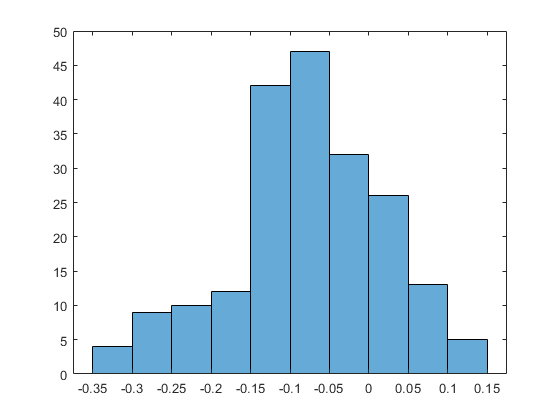

erboi = (yhat-yt);
histogram((erboi)');

VAF = 1-var(erboi)/var(yt)

VAF = 0.2896

MSE = immse(yhat,yt)

MSE = 0.0152

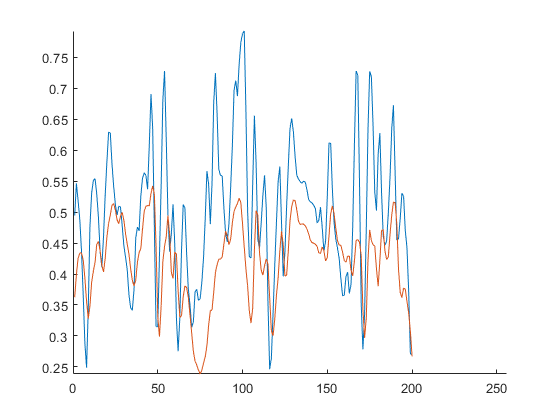


figure
hold on
plot(yt)
plot(yhat)
hold off
axis([0 256 -inf inf])

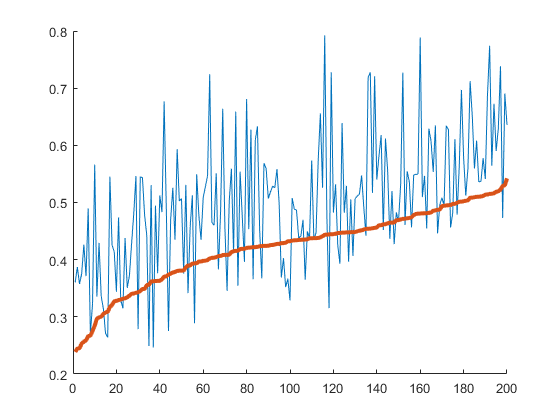


%  Visualize errors
[sortout,Iss]=sort(yhat);
figure
hold on
plot(yt(Iss))
plot(sortout,'Linewidth',3)
hold off

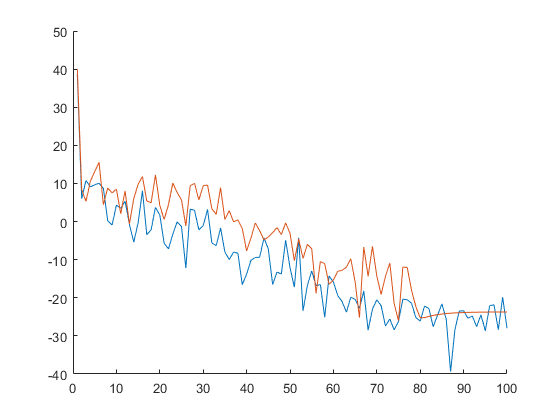


FY = mag2db(abs(fft(yhat)));
FZ = mag2db(abs(fft(yt)));

figure;
hold on
plot(FY(1:floor(end/2)))
plot(FZ(1:floor(end/2)))
hold off